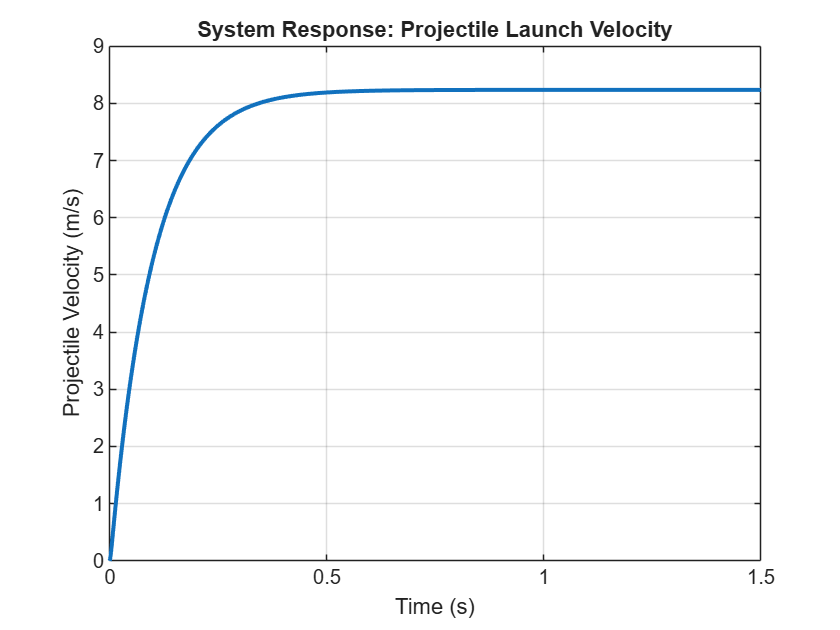

% Projectile Launcher Simulation Script
clear all; clc;

% --- 1. System Parameters ---
V_input = 12;   % Volts
R = 0.5;        % Ohms
L = 0.001;      % Henrys
Kt = 0.05;      % Torque Constant
Ke = 0.05;      % Back-EMF Constant
J = 0.0005;     % Flywheel Inertia
B = 0.0001;     % Friction
r = 0.035;      % Flywheel Radius (m)

% --- 2. Define the Dynamics (ODE) ---
% x(1) is Current, x(2) is Angular Velocity
motor_ode = @(t, x) [
    (V_input - x(1)*R - Ke*x(2)) / L;      % di/dt
    (Kt*x(1) - B*x(2)) / J                 % domega/dt
];

% --- 3. Run Simulation ---
tspan = [0 1.5];
x0 = [0; 0];
[t, x] = ode45(motor_ode, tspan, x0);

% --- 4. Results ---
omega = x(:,2);
v_launch = omega * r; % Linear Velocity

% --- 5. Plotting ---
plot(t, v_launch, 'LineWidth', 2);
grid on;
xlabel('Time (s)');
ylabel('Projectile Velocity (m/s)');
title('System Response: Projectile Launch Velocity');